syms Mr Jr Mt Jt B R eta gr g l x(t) beta(t) Cm(t) K_x K_beta

lagrange_x = (Mr+Jr/(R^2)+Mt)*diff(x,t,2) + Mt*l*cos(beta)*diff(beta,t,2) - Mt*l*sin(beta)*diff(beta,t,1)^2 + B*diff(x,t,1)/(R^2) == Cm*eta*gr/R

$$lagrange\_x(t) = \left(\mathrm{Mr}+\mathrm{Mt}+\frac{\mathrm{Jr}}{R^{2}}\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{B\,\frac{\partial }{\partial t}x\left(t\right)}{R^{2}}-\mathrm{Mt}\,l\,\sin\left(\beta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+\mathrm{Mt}\,l\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)=\frac{\eta \,\mathrm{gr}\,\mathrm{Cm}\left(t\right)}{R}$$


lagrange_beta = (Mt*l^2+Jt)*diff(beta,t,2) + Mt*l*diff(x,t,2)*cos(beta) - Mt*g*l*sin(beta) == -Cm*eta

$$lagrange\_beta(t) = \left(\mathrm{Mt}\,l^{2}+\mathrm{Jt}\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+\mathrm{Mt}\,l\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-\mathrm{Mt}\,g\,l\,\sin\left(\beta \left(t\right)\right)=-\eta \,\mathrm{Cm}\left(t\right)$$


control = Cm == -K_x*x - K_beta*beta

$$control(t) = \mathrm{Cm}\left(t\right)=-K_{\beta }\,\beta \left(t\right)-K_{x}\,x\left(t\right)$$


lagrange_x = subs(lagrange_x, [Mr, Jr, Mt, Jt, B, R, eta, gr, g, l, K_x, K_beta], [1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0])

$$lagrange\_x(t) = \cos\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)-\sin\left(\beta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+\frac{\partial }{\partial t}x\left(t\right)+3\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\mathrm{Cm}\left(t\right)$$

lagrange_beta = subs(lagrange_beta, [Mr, Jr, Mt, Jt, B, R, eta, gr, g, l, K_x, K_beta], [1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0])

$$lagrange\_beta(t) = \cos\left(\beta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-\sin\left(\beta \left(t\right)\right)+2\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)=-\mathrm{Cm}\left(t\right)$$

control = subs(control, [Mr, Jr, Mt, Jt, B, R, eta, gr, g, l, K_x, K_beta], [1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0])

$$control(t) = \mathrm{Cm}\left(t\right)=0$$


eqns = [lagrange_x lagrange_beta control];
vars = [x(t); beta(t); Cm(t)];

[eqns,vars] = reduceDifferentialOrder(eqns,vars);

isLowIndexDAE(eqns,vars)

ans = logical
   1



f = daeFunction(eqns,vars)

f = function_handle with value:
    @(t,in2,in3)[-in2(3,:)+in2(4,:)+in3(4,:).*3.0+in3(5,:).*cos(in2(2,:))-in2(5,:).^2.*sin(in2(2,:));in2(3,:)+in3(5,:).*2.0-sin(in2(2,:))+in3(4,:).*cos(in2(2,:));in2(3,:);in2(4,:)-in3(1,:);in2(5,:)-in3(2,:)]


%F = @(t,Y,YP) f(t,Y,YP);

opt = odeset('RelTol', 10.0^(-3),'AbsTol',10.0^(-3));

vars

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \beta \left(t\right)\\ \mathrm{Cm}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ {\mathrm{Dbeta}}_{t}\left(t\right) \end{array}\right)$$


ti=0;
tf=3;
timespan = [ti tf];

y0 = [0;-0.1;1;0;0];
yp0 = [0;0;0;0;0];

[y0,yp0] = decic(f,ti,y0,[1 1 0 0 0],yp0,[]);

y0

y0 =          0
   -0.1000
         0
         0
         0


yp0

yp0 =          0
         0
         0
    0.0198
   -0.0598


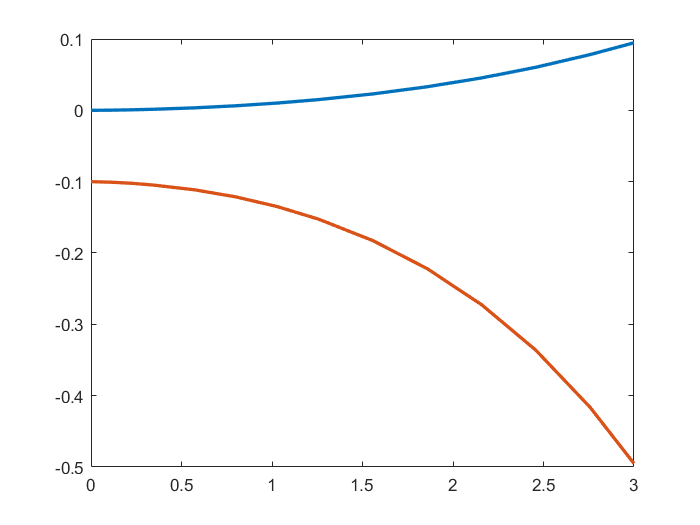


[tSol, ySol] = ode15i(f,timespan,y0,yp0,opt);
plot(tSol',[ySol(:,1), ySol(:,2)],'LineWidth',2)